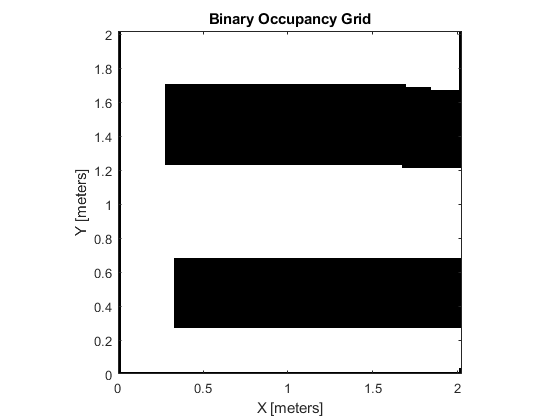

% Load the image
img = imread('C:\Users\frede\OneDrive\Dokumenter\6_semester\ANS\projekt\Testmap1.png');


% Convert the image to grayscale
gray_img = rgb2gray(img);

% Convert the grayscale image to a binary image
binary_img = imbinarize(gray_img);
    
% Create a binary occupancy map from the binary image
scale_factor = 500;   %500 pixels pr. meter
map = binaryOccupancyMap(binary_img,scale_factor);

% Resize the map to be 10 times larger


%resized_map = imresize(map.occupancyMatrix, scale_factor);

% Create a new binary occupancy map from the resized matrix
new_map = binaryOccupancyMap(map);

% Show the map
show(new_map);

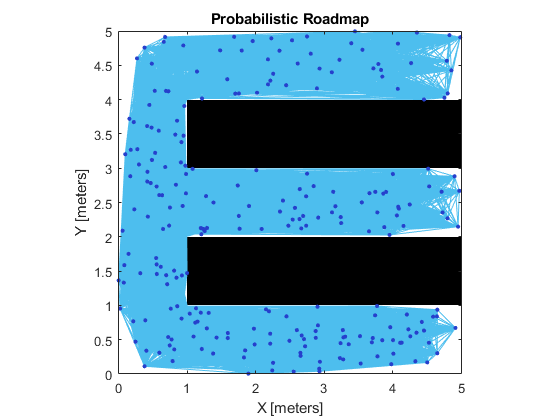

%Create points
prmComplex = mobileRobotPRM(new_map,250);
show(prmComplex)

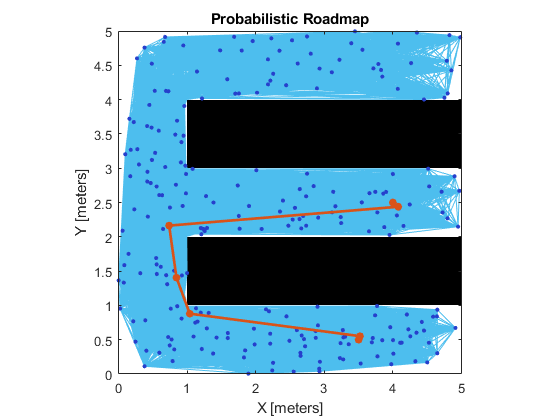

%Define start location
startLocation1 = [3.5 0.5];
endLocation1 = [4 2.5];
path = findpath(prmComplex,startLocation1,endLocation1);
show(prmComplex)

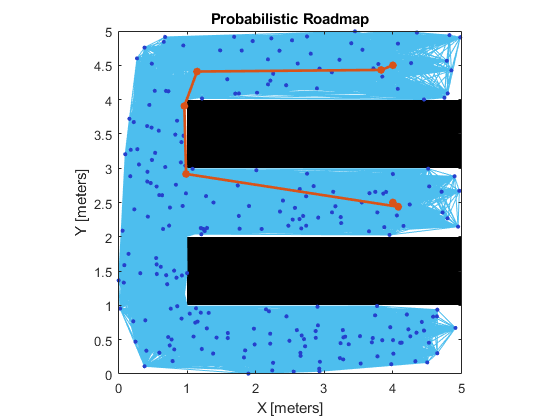


endLocation2 = [4 4.5];
path = findpath(prmComplex,endLocation1,endLocation2);
show(prmComplex)

%   